# Создаю свой Байесовский Классификатор

#### 1. Нахожу мат ожидания и дисперсии отчетов спектра для каждой ноты используя выборку для обучения

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

data - Каждый столбец - звук отдельной **ноты**

NOTES = 88;
data = reshape(z,4*Fs,[]);
NFFT = 1024;

t_one = 2;                  % Одна нота длится 2 секунды
dt = 1/Fs;                  % Время между отчетами
t_min = NFFT*dt;            % Время вырезки
N_row = floor(t_one/t_min); % Количество вырезок за 2 секунды
N = N_row;

save('Constants.mat', 'N', 'NFFT', 'NOTES', 'Fs')

Получаю выборку для обучения

Y = zeros(N_row*NOTES, 1);
X = zeros([N_row*NOTES, NFFT]);

for num_notes = 1 : NOTES
    
    N1 = N * (num_notes-1) + 1;
    N2 = N1 + N - 1;
    
    d = data(1:NFFT*N, num_notes);
    d1 = reshape(d, [N, NFFT]);
    
    X(N1:N2, :) = d1;
    Y(N1:N2) = num_notes;
   
end

cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);
XTest_spec = XTest;         % or = zero(XTest)
XTrain_spec = XTrain;

for i = 1:length(XTest)
    XTest_spec(i, :) = abs(fft(XTest(i, :)));
end
for i = 1:length(XTrain)
    XTrain_spec(i, :) = abs(fft(XTrain(i, :)));
end

save('dataTrainTest.mat', 'XTrain', 'YTrain', 'XTest', 'YTest', 'XTest_spec', 'XTrain_spec')

Нахожу mean и std ***тренировочной выборки***

*mean_pdf* - Массив. Каждый столбец хранит **средние значения** **спектральных** отчетов для выбранной ноты.

*std_pdf* - Массив. Каждый столбец хранит **дисперсию** **спектральных** отчетов для выбранной ноты.

mean_pdf = zeros([NFFT, NOTES]);
std_pdf = zeros([NFFT, NOTES]);

for num_notes = 1 : NOTES
    notes = reshape(data(1:NFFT*N,num_notes),NFFT,N);
    % notes = abs(fft(notes));
    mean_pdf(:,num_notes) = mean(notes(1:NFFT,:),2);
    std_pdf(:,num_notes) = std(notes(1:NFFT,:),1,2);   % Maybe we must set 0 for secod parameter
end


mean_pdf_spec = zeros([NFFT, NOTES]);
std_pdf_spec = zeros([NFFT, NOTES]);

for num_notes = 1 : NOTES
    ind = find(YTest==num_notes);
    X_cur = XTrain_spec(ind, :);
    mean_pdf_spec(:,num_notes) = mean(X_cur,1)';
    std_pdf_spec(:,num_notes) = std(X_cur,1,1)';
end

save('GaussData.mat', 'mean_pdf', 'std_pdf', 'mean_pdf_spec', 'std_pdf_spec')

#### 2. Строю Гауссы по заданным параметрам (для примера работы)

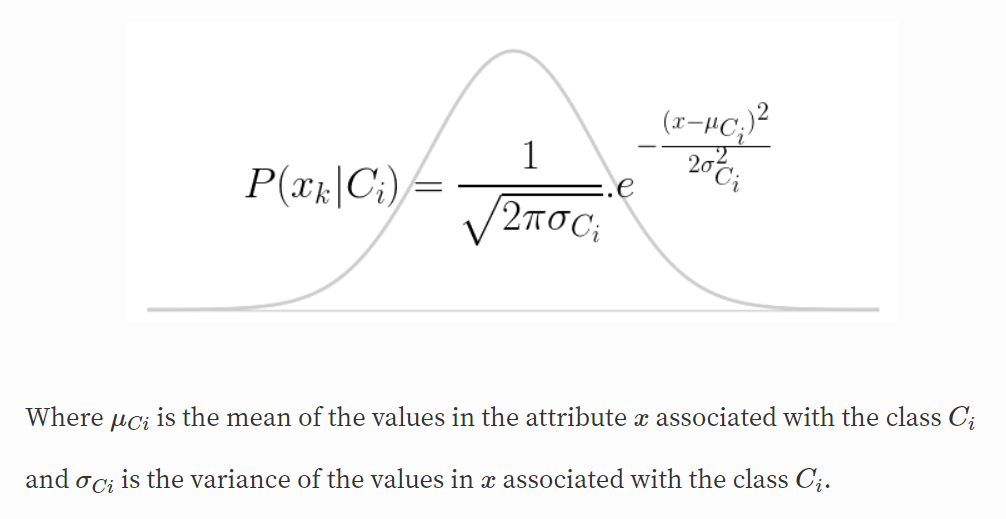

 params = [std mean]

Из митинга зум - Варианты путей развития - 

- (своими руками Гаусс)

- (настроить такую же модель по SVM)

# Пример Байесовского Классификатора своими руками на основе спектральных сигналов

Беру одну случайную вырезку из данных для тренировки

rand_ind = randi(length(XTest));
test_sig = XTest_spec(rand_ind, :);
test_label = YTest(rand_ind);

Находим вероятности 

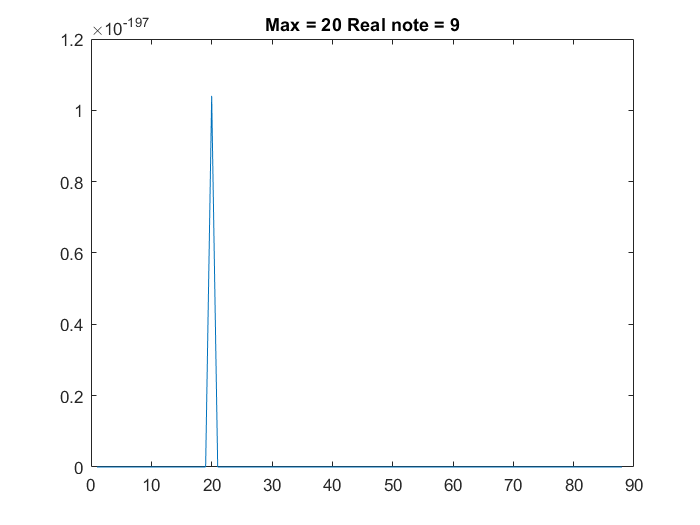

Prob_note = zeros([NOTES, 1]);       % Вероятность для каждой ноты
Prob_note_cuts = zeros([N, 1]);      % Вероятность для каждой вырезки одной ноты
Prob_samples = zeros([NFFT, 1]);     % Вероятность для каждого отчета одной вырезки

for i = 1:NOTES
    
    for j = 1:N
        
        Pci = 1; % Initial prior probability for this note P(Cj)
        Prob_note_cuts(j) = Pci;
        
        for k = 1:NFFT
            
            x = test_sig(k);    % Current sample of signal
            % p = 1;  % Current probability of one sample
            std_cur = std_pdf_spec(k, i);    % Current std
            mean_cur = mean_pdf_spec(k, i);  % Current mean
            
            %p = p * exp(-(((x-mean_cur)^2) /(2*std_cur^2)));
            %p = p / sqrt(2*pi*std_cur);
            
            p = gaussmf(x, [std_cur mean_cur]);
            % p = p / sqrt(2*pi*std_cur);
            
            Prob_samples(k) = p;
            Prob_note_cuts(j) = Prob_note_cuts(j) * Prob_samples(k);
        end
           
    end
    
    Prob_note(i) = max(Prob_note_cuts);
end

figure
plot(Prob_note)
title("Max = " + string(find(Prob_note==max(Prob_note))) + " Real note = " + string(test_label))

# Этот код неправильный, но я использую его части (напутал концепцию)

clear all
close all

load('GaussData.mat')
load('dataTrainTest.mat')
load('Constants.mat')


Ниже представлен анализ тестовой выборки. В 3Д массив Prob_all будут записаны результаты

% 3D matrix where each cell represents each note. Row represents a 1024 samples
% of this note, column represents probability for each element of signal (spectrum sample)
Prob_all = zeros(NOTES, N, NFFT);

% Select each note separately
for note = 1:NOTES
    
    % Make an array with indexes for those samples
    % Which corresponds for one note. For example 
    % For note "1" we get 1...26 and so on.
    ind = find(YTest==note); 
    
    X_note = XTest(ind, :);
    Y_note = YTest(ind, :);
    
    std_note = std_pdf(:, note);
    mean_note = mean_pdf(:, note);
    
    % Get each 1024 signal (each cut)
    % Usually it vary from 25 to 26
    for j = 1:length(ind)
        
        % Initial probability for this note P(Cj)
        % In future will be replaced with prior probability 
        prob = 1;  
        
        % Calculate Gauss for each sample
        for k = 1:NFFT
            
            x = X_note(j, k);
            std_cur = std_note(k);
            mean_cur = mean_note(k);
            
            prob = prob * gaussmf(x, [std_cur mean_cur]);
            prob = prob / sqrt(2*pi*std_cur);
            
            Prob_all(note, j, k) = prob;
            
        end
        
    end
    
    % Now we have length(ind) probabilities 
      
end

save("Prob_all.mat", "Prob_all")